## EKG signal

clc; clear all; close all;

load('EKGizo1.mat')
plot(x)

### FIR EKG filter designed in filterdesigner

- Fs = 500

- Fc = 2

- order must be even (otherwise distorts frequency)

load('EKGfilter.mat')

y = filter(Num, 1, x);
hold on
plot(y)

### IIR Butterworth

- uses SOS and G coefficients, must be converted (or use different function)

- has group delay, highest around Fc

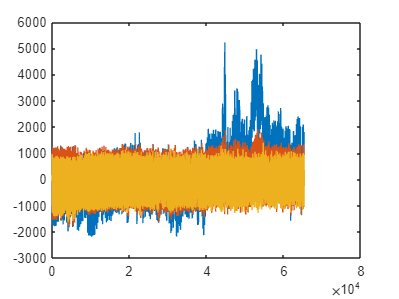

load("EKGfilterIIR.mat")
[B, A] = sos2tf(SOS, G);
y = filter(B, A, x);
hold on
plot(y)